clear

prompt = 'type "0" to aproximate loop length by selecting its footpoints and "1" -- by the highest point and the center: ';
l = input(prompt);
R = zeros(10,1);
for i=1:10
    disp(i)
    imshow 20_01_active_region.png
    [x(:,i),y(:,i),P_temp] = impixel; % left mouse button to select first point, 
                                      %right to select second point
    clear P_temp

    %save('x.mat','x');
    %save('y.mat','y'); 
    R(i,1) = sqrt( (x(1,i)-x(2,i))^2 + (y(1,i)-y(2,i))^2 );
end

R = mean(R);

if (l==0)
    L = 3.14*R/2;
else
    L = 3.14*R;
end

Lm = 725*10^3*L*0.6;
L_Mm = Lm/10^6;

disp('loop length is: ')
disp([num2str(L) ' pixels'])
disp([num2str(Lm) ' m'])
disp([num2str(L_Mm) ' Mm'])
save('L_Mm.mat','L_Mm')

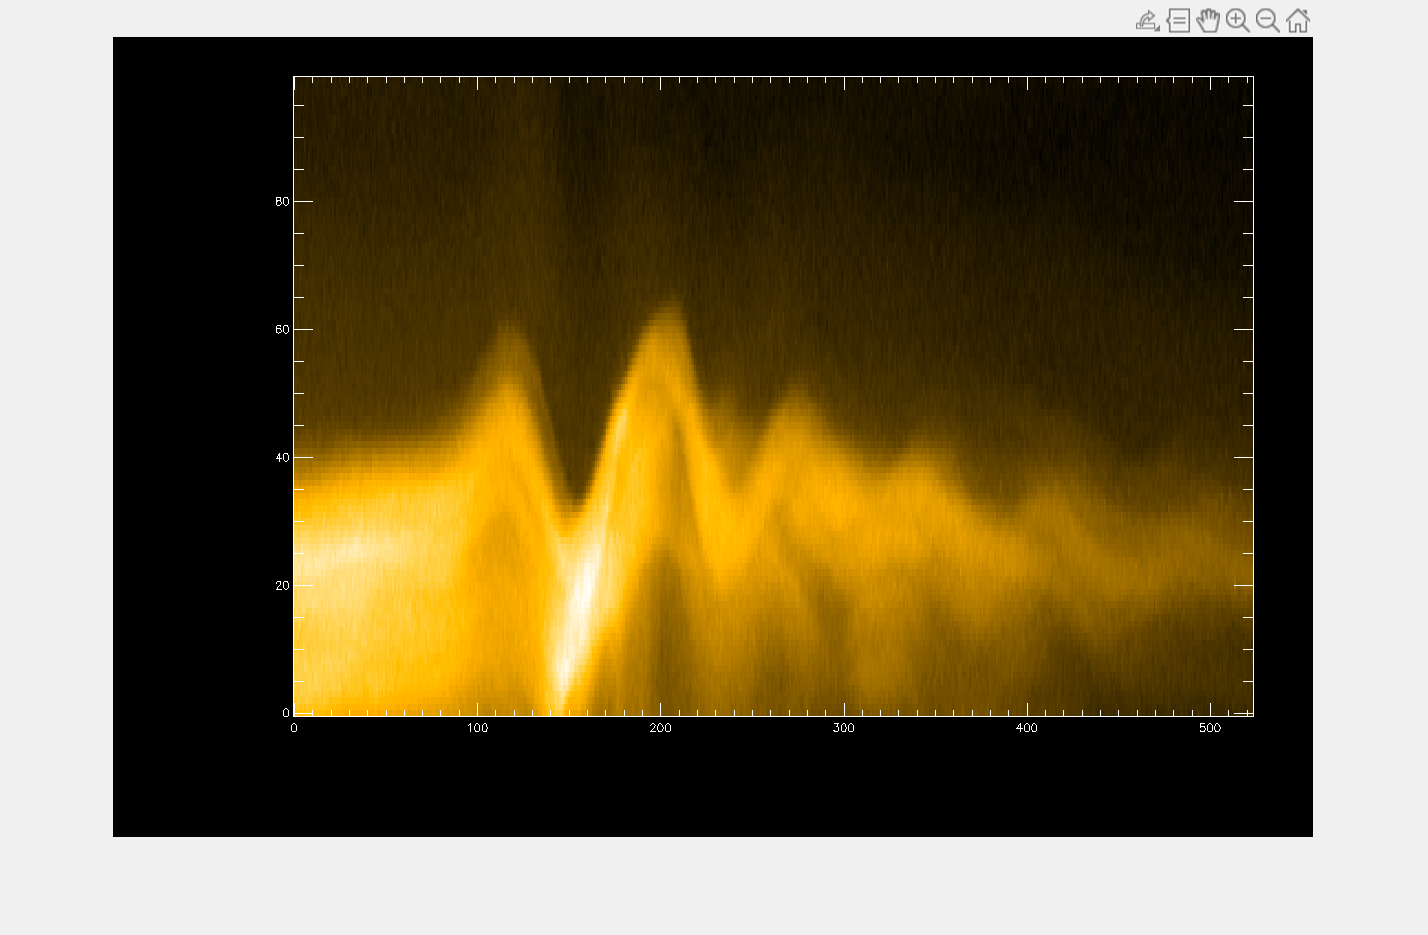

xi =    328
   345
   351
   360
   367
   387
   412
   423
   429
   436


yi =    416
   383
   363
   337
   315
   287
   302
   336
   355
   379


P =    202   140     0
   131    91     0
   108    75     0
    89    62     0
    70    49     0
    92    64     0
    98    68     0
   126    87     0
   113    78     0
   101    70     0


clear
imshow 20_01_33_td_map.png
[xi,yi,P] = impixel % left mouse button to select points, right to close


save('xi.mat','xi');
save('yi.mat','yi');

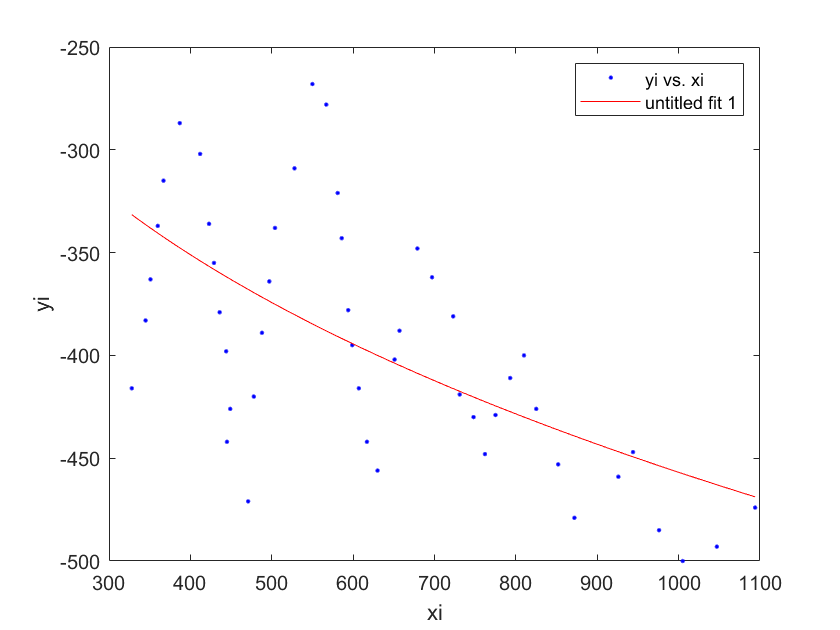

clear
load('xi.mat')
load('yi.mat')
yi = -yi;

[xData, yData] = prepareCurveData( xi, yi );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares');
opts.Display = 'Off';
opts.StartPoint = [0.913375856139019 0.63235924622541];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'yi vs. xi', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'xi', 'Interpreter', 'none' );
ylabel( 'yi', 'Interpreter', 'none' );

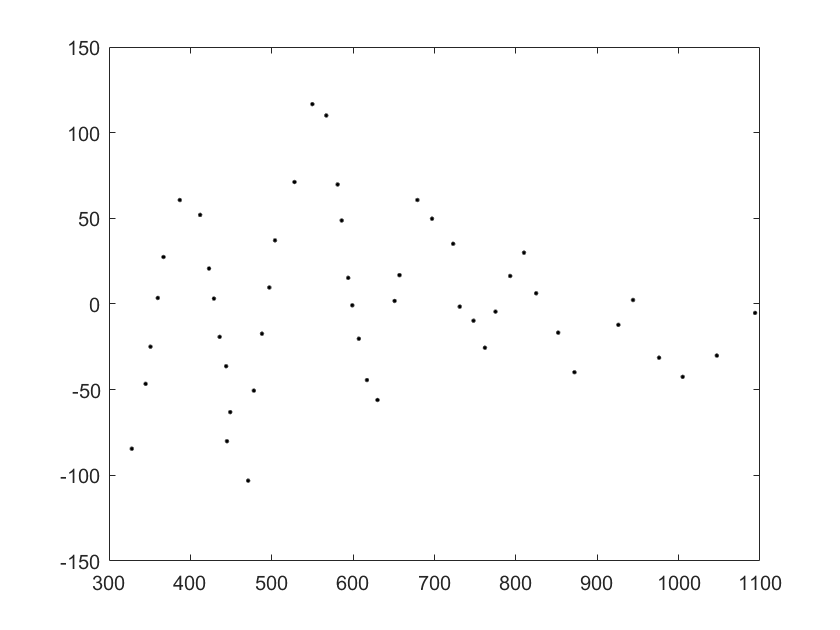


y = yi - fitresult(xi);
figure
plot(xi,y,'k.')

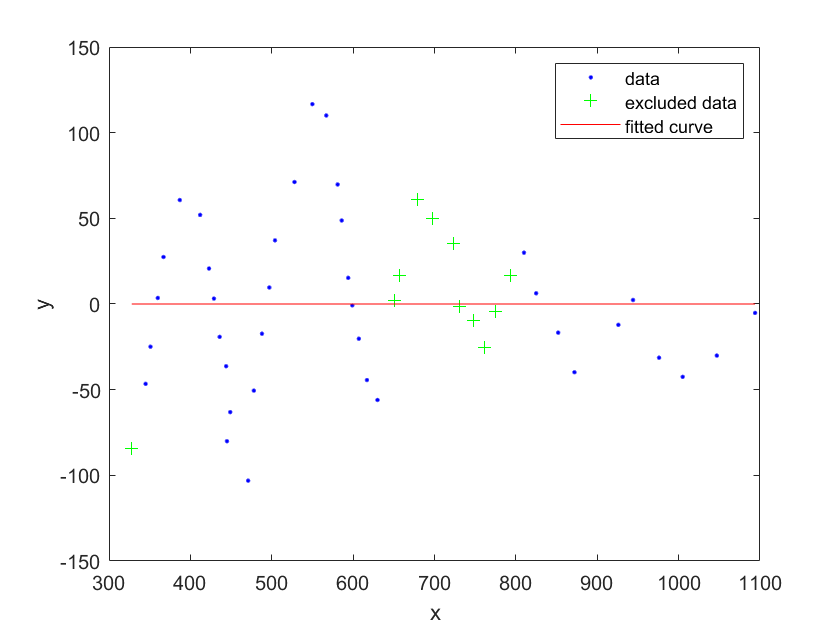


[xData, yData] = prepareCurveData( xi, y );
ft = fittype( 'a*sin(b*x+c)*exp(-d*x)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 29 30 31 32 33 34 35 36 37 38] );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf -Inf];
opts.StartPoint = [10 0.045 0.059 0.001];
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult1, gof1] = fit( xData, yData, ft, opts );

h = plot( fitresult1, xData, yData, excludedPoints );

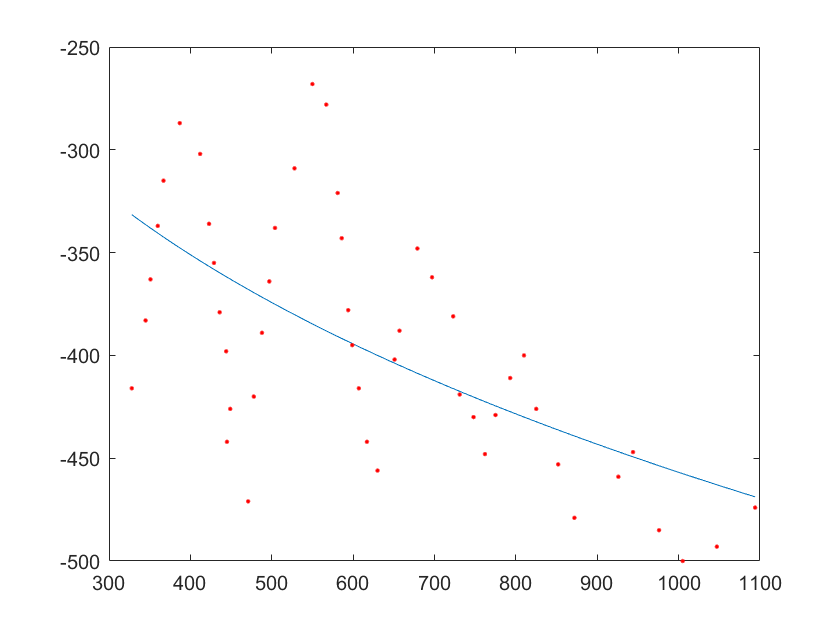


xtimes = linspace(min(xi),max(xi),100);
ytimes = fitresult1(xtimes) + fitresult(xtimes);
figure
plot(xtimes,ytimes)
hold on
plot(xi,yi,'r.')


c = coeffvalues(fitresult1)

c =     7.2991    0.0552    6.0502    1.5001


P = 2*pi/c(2)*12/60

P = 22.7574